# **Ejercicio 3**

## Leemo**s los datos de reconocimiento de objetos del agregador de datos (últimas 2 horas)**

readChannelID = 1428584;
LabelFieldID = 1;
readAPIKey = '';

dataForLastHours = thingSpeakRead(readChannelID, ...
    'Fields', LabelFieldID,'NumMinutes', 120, ...
    'ReadKey',readAPIKey, 'OutputFormat', 'table');

## Creamos una figura 

figure;

## Visualizamos los datos usando un histograma

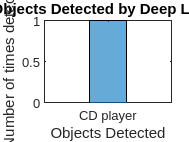

if (not(isempty(dataForLastHours)))
    labelsForLastHours = categorical(dataForLastHours.Label);
    numbins = min(numel(unique(labelsForLastHours)), 20);
    histogram(labelsForLastHours, 'DisplayOrder', 'descend', ...
        'NumDisplayBins', numbins);
    xlabel('Objects Detected');
    ylabel('Number of times detected');
    title('Histogram: Objects Detected by Deep Learning Network');
    set(gca,'FontSize', 10)
end

drawnow

## Visualizamos los datos con un mosaico de palabras

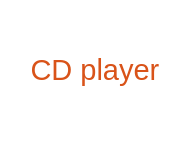

wordcloud(labelsForLastHours)